%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%  ACTIVIDAD 3 - Robot Cartesiano de 4 GDL
%  Código en MATLAB para el cálculo de las transformaciones homogéneas,
%  Jacobiano lineal y Jacobiano angular (velocidades) de un robot cartesiano 
%  de 4 grados de libertad (todas juntas prismáticas).
%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Limpiar el espacio de trabajo y la ventana de comandos
clear all
close all
clc

%% 1) Declaración de variables simbólicas
% Cada 'l_i(t)' representa la posición de la junta i (prismática en este caso).
syms l1(t) l2(t) l3(t) l4(t) t 

%% 2) Configuración del robot
% Vector RP indica el tipo de cada articulación:
%  0 = rotacional (R), 1 = prismática (P).
% En este caso, 4 juntas prismáticas:
RP = [1 1 1 1];

% Vector de coordenadas articulares (variables generalizadas)
Q = [l1, l2, l3, l4];

% Vector de velocidades generalizadas (derivada respecto al tiempo)
Qp = diff(Q, t);

% Número de grados de libertad (GDL)
GDL = size(RP, 2); 
disp(['El robot tiene ', num2str(GDL), ' grados de libertad.']);

El robot tiene 4 grados de libertad.



%% 3) Definir matrices de posición P y rotación R para cada articulación
% El robot cartesiano se modela haciendo que cada articulación se desplace 
% sobre el eje z de su propio marco local. Para ello, reorientamos z_i con 
% rotaciones adecuadas (o la dejamos en identidad si no se requiere).

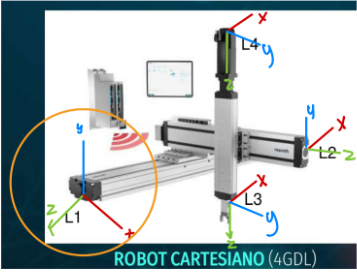

% Articulación 1:
% Posición relativa al marco 0
P(:,:,1) = [0; 0; l1];
R(:,:,1) = [ 0  0  1;   % +90° en el eje Y, 
             0  1  0;   %  para alinear z1 con x0 (según convención anterior).
            -1  0  0];

% Articulación 2:
% Posición relativa al marco 1
P(:,:,2) = [0; 0; l2];

% Matriz de rotación R2 respecto al marco 1
%  De nuevo, +90° en x o y para alinear z2 con y0, etc.
R(:,:,2) = [ 1  0  0;   % +90° en X (o Y) según la convención del robot 3GDL
             0  0  -1;
             0  1  0];

% Articulación 3:
% Posición relativa al marco 2
P(:,:,3) = [0; 0; l3];
% Sin rotación adicional, se deja como identidad
R(:,:,3) = eye(3);

% Articulación 4:
% Posición relativa al marco 3
P(:,:,4) = [0; 0; l4];
% Sin rotación adicional, se deja como identidad
R(:,:,4) = eye(3);

%% 4) Construcción de las matrices de transformación homogénea
% Creamos un vector de ceros para la última fila de cada matriz [0 0 0 1]
Vector_Zeros = [0 0 0];

% Inicializamos arreglos A y T
% A(:,:,i) = Transformación local de la articulación i
% T(:,:,i) = Transformación global desde el marco base hasta la articulación i
for i = 1:GDL
    
    % Matriz de transformación homogénea local A_i
    A(:,:,i) = simplify([ R(:,:,i), P(:,:,i);
                          Vector_Zeros, 1      ]);
    
    % Matriz de transformación global T_i
    if i == 1
        % La primera articulación se define respecto al marco base
        T(:,:,i) = A(:,:,i);
    else
        % El resto se obtiene multiplicando T anterior por A_i
        T(:,:,i) = T(:,:,i-1)*A(:,:,i);
    end
    
    % Extraemos la rotación y posición global de la articulación i
    RO(:,:,i) = T(1:3,1:3,i);
    PO(:,:,i) = T(1:3,4,i);
    
    % Mostrar la matriz T_i en pantalla
    disp(['Matriz de Transformación global T', num2str(i), ':']);
    disp(simplify(T(:,:,i)));
end

Matriz de Transformación global T1:


$$\left(\begin{array}{cccc} 0 & 0 & 1 & 0\\ 0 & 1 & 0 & 0\\ -1 & 0 & 0 & l_{1}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matriz de Transformación global T2:


$$\left(\begin{array}{cccc} 0 & 1 & 0 & l_{2}\left(t\right)\\ 0 & 0 & -1 & 0\\ -1 & 0 & 0 & l_{1}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matriz de Transformación global T3:


$$\left(\begin{array}{cccc} 0 & 1 & 0 & l_{2}\left(t\right)\\ 0 & 0 & -1 & -l_{3}\left(t\right)\\ -1 & 0 & 0 & l_{1}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matriz de Transformación global T4:


$$\left(\begin{array}{cccc} 0 & 1 & 0 & l_{2}\left(t\right)\\ 0 & 0 & -1 & -l_{3}\left(t\right)-l_{4}\left(t\right)\\ -1 & 0 & 0 & l_{1}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$


%% 5) Cálculo del Jacobiano lineal (diferencial) para el efector final
% Usamos functionalDerivative para derivar la posición final (del GDL) 
% con respecto a cada variable l_i.

% Extraemos las coordenadas x, y, z del efector (articulación 4) en el marco 0
x_end = PO(1,1,GDL);
y_end = PO(2,1,GDL);
z_end = PO(3,1,GDL);

% Derivadas parciales de x, y, z respecto a l1, l2, l3, l4
Jv11 = functionalDerivative(x_end, l1);
Jv12 = functionalDerivative(x_end, l2);
Jv13 = functionalDerivative(x_end, l3);
Jv14 = functionalDerivative(x_end, l4);

Jv21 = functionalDerivative(y_end, l1);
Jv22 = functionalDerivative(y_end, l2);
Jv23 = functionalDerivative(y_end, l3);
Jv24 = functionalDerivative(y_end, l4);

Jv31 = functionalDerivative(z_end, l1);
Jv32 = functionalDerivative(z_end, l2);
Jv33 = functionalDerivative(z_end, l3);
Jv34 = functionalDerivative(z_end, l4);

% Jacobiano lineal de forma diferencial (3x4)
jv_d = simplify([
    Jv11, Jv12, Jv13, Jv14;
    Jv21, Jv22, Jv23, Jv24;
    Jv31, Jv32, Jv33, Jv34
]);
disp('Jacobiano lineal (diferencial) jv_d = ');

Jacobiano lineal (diferencial) jv_d = 


disp(jv_d);

$$\left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & 0 & -1 & -1\\ 1 & 0 & 0 & 0 \end{array}\right)$$


%% 6) Cálculo del Jacobiano (analítico) para cada articulación
% Jv_a (3xGDL) -> partes lineales
% Jw_a (3xGDL) -> partes angulares

% Inicializamos Jv_a y Jw_a como matrices simbólicas 3x4
Jv_a = sym(zeros(3,GDL));
Jw_a = sym(zeros(3,GDL));

for k = 1:GDL
    if RP(k) == 0
        % Caso: junta rotacional
        % El vector z_{k-1} define la dirección del eje de giro.
        % Se usa cross(z_{k-1}, p_n - p_{k-1}) para la parte lineal.
        if k == 1
            % No hay marco previo, z_0 se asume [0;0;1]
            Jv_a(:,k) = cross([0;0;1], PO(:,:,GDL));
            Jw_a(:,k) = [0;0;1];
        else
            Jv_a(:,k) = cross(RO(:,3,k-1), PO(:,:,GDL) - PO(:,:,k-1));
            Jw_a(:,k) = RO(:,3,k-1);
        end
    else
        % Caso: junta prismática
        % El vector z_{k-1} define la dirección de traslación.
        if k == 1
            % Si es la primera articulación, z_0 se asume [0;0;1]
            Jv_a(:,k) = [0;0;1];
        else
            Jv_a(:,k) = RO(:,3,k-1);
        end
        % La velocidad angular de una junta prismática es cero
        Jw_a(:,k) = [0;0;0];
    end
end

% Simplificar expresiones simbólicas
Jv_a = simplify(Jv_a);
Jw_a = simplify(Jw_a);

disp('Jacobiano lineal (analítico) Jv_a = ');

Jacobiano lineal (analítico) Jv_a = 


disp(Jv_a);

$$\left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & 0 & -1 & -1\\ 1 & 0 & 0 & 0 \end{array}\right)$$

disp('Jacobiano angular (analítico) Jw_a = ');

Jacobiano angular (analítico) Jw_a = 


disp(Jw_a);

$$\left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$


%% 7) Cálculo de velocidades lineales y angulares del efector final
% V = Jv_a * Qp^T
% W = Jw_a * Qp^T

V = simplify(Jv_a * Qp.');
W = simplify(Jw_a * Qp.');

disp('Velocidad lineal del efector (V) = ');

Velocidad lineal del efector (V) = 


disp(V);

$$\left(\begin{array}{c} \frac{\partial }{\partial t}l_{2}\left(t\right)\\ -\frac{\partial }{\partial t}l_{3}\left(t\right)-\frac{\partial }{\partial t}l_{4}\left(t\right)\\ \frac{\partial }{\partial t}l_{1}\left(t\right) \end{array}\right)$$

disp('Velocidad angular del efector (W) = ');

Velocidad angular del efector (W) = 


disp(W);

$$\left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$